# Tutorial March 12 Franklin Example 7.2 p484

clearvars, clc, close all

m = 1500;
b = 60; 
u = 750; 

A = [0 , 1;0, -b/m]

A =          0    1.0000
         0   -0.0400


B = [0;1/m]

B = 1.0e-03 *

         0
    0.6667


C = [0 1]

C =      0     1


D = 0

D = 0

sys  = ss(A,B,C, D)


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2      0  -0.04
 
  B = 
              u1
   x1          0
   x2  0.0006667
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



G = tf(1/m, [1 b/m])


G =
 
  0.0006667
  ---------
  s + 0.04
 
Continuous-time transfer function.



s = tf('s')


s =
 
  s
 
Continuous-time transfer function.


G1 = (1/m)/(s+b/m)


G1 =
 
  0.0006667
  ---------
  s + 0.04
 
Continuous-time transfer function.


calculate the step response:

[ys,ts] = step(sys); % use state-space systme
[yg, tg]  =step(G); % directly use the transfer function

Also use the simulink data

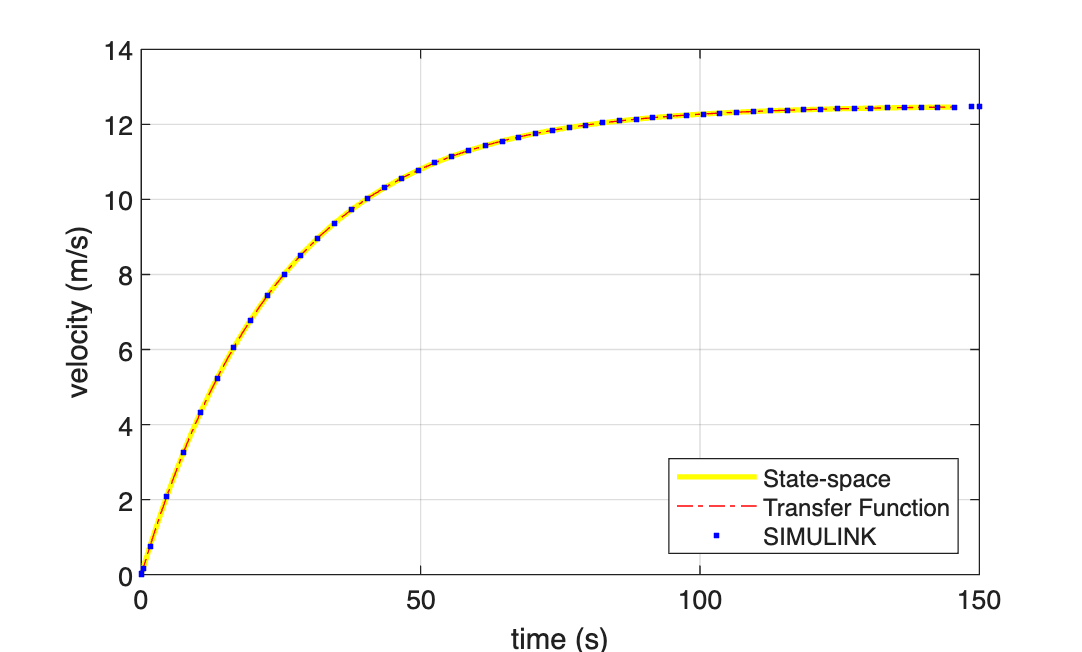

simdat = sim('Franklin_ex_7_2_sim.slx');

figure(1)
plot(ts,u*ys,'y','LineWidth',2,'DisplayName','State-space')
hold on
plot(tg,u*yg,'r-.','DisplayName','Transfer Function')
% Next line: SIMULIUNK data:
plot(simdat.ScopeData.time,simdat.ScopeData.signals.values,...
'b.','DisplayName','SIMULINK')
hold off
xlabel('time (s)')
ylabel('velocity (m/s)')
grid on
legend(Location="southeast")